**Discretización de un sistema LTI de segundo orden de tiempo continuo**

Valores de los parámetros del sistema según la ecuación diferencial descrita en el documento de la tarea correspondiente

m=30;
b=20;
k=50;

Cálculo de las constantes de la función de transferencia en tiempo continuo

b1=b/m;
a1=b1;
b2=k/m;
a2=b2;

Para discretizar el sistema se considerará el siguiente periodo de muestreo

Ts=0.13;

Aplicando la transformación se obtienen las siguiente cosntantes de la función de transferencia de tiempo discreto (dominio z)

B1=-b1/Ts;
B2=(b1/Ts)+b2;
A0=1/Ts^2;
A1=-(2/Ts^2)-(a1/Ts);
A2=(1/Ts^2)+(a1/Ts)+a2;

Una vez se tienen las constantes se construyen las funciones de transferencia, tanto al de tiempo discreto como la de tiempo continuo

sys_s=tf([0 b1 b2],[1 a1 a2])

sys_s =
 
     0.6667 s + 1.667
  ----------------------
  s^2 + 0.6667 s + 1.667
 
Continuous-time transfer function.



sys_z=tf([B2 B1 0],[A2 A1 A0],Ts)

sys_z =
 
      6.795 z^2 - 5.128 z
  ---------------------------
  65.97 z^2 - 123.5 z + 59.17
 
Sample time: 0.13 seconds
Discrete-time transfer function.



Ahora en un solo gráfico se representarán las respuestas al impulso unitario de ambos sistemas para que realice la comparación. Revise la ayuda de la función tf(...) para aclarar las posibles dudas que surjan de su uso.

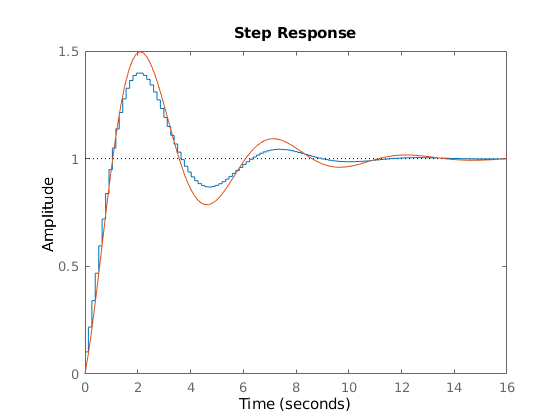

figure
hold on
step(sys_z)
step(sys_s)
hold off

Realice cambios sobre el valor del periodo de muestreo Ts, ¿Qué observa?, ¿Qué puede concluir del ejercicio?